clear all
close all
clc

s=tf('s');

[file_controllers, file_path] = uigetfile("controller_*.mat", "Controller");
load([file_path file_controllers])

[file_name, file_path] = uigetfile("*.mat", "Modello1");
load([file_path file_name])

[file_name, file_path] = uigetfile("*.mat", "Modello2");
load([file_path file_name])

F1_in=minreal(feedback(C1_in*modello_continuo_tf_j1,1))

F1_in =
 
  From input "u1" to output:
                                             
  2.142e05 s^5 + 5.778e07 s^4 + 1.298e11 s^3 
                                             
          + 2.198e13 s^2 + 1.44e16 s         
                                             
                                + 1.58e17    
                                             
  -------------------------------------------
                                           
    s^7 + 1893 s^6 + 2.051e06 s^5          
                                           
            + 1.254e09 s^4 + 6.516e11 s^3  
                                           
            + 1.358e14 s^2 + 2.123e16 s    
                                           
                                  + 1.58e17
                                           
 
Continuous-time transfer function.



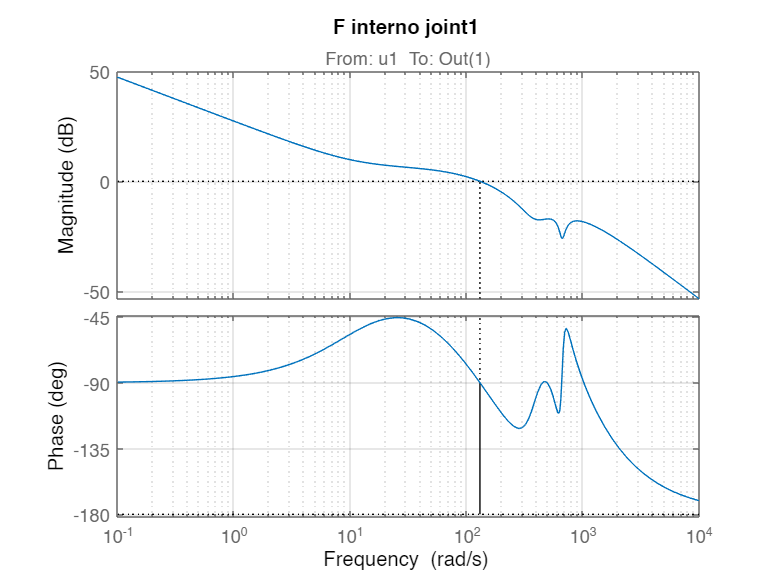

margin(C1_in*modello_continuo_tf_j1)
grid on
title("F interno joint1")


F2_in=minreal(feedback(C2_in*modello_continuo_tf_j2,1))

F2_in =
 
  From input "u1" to output:
                                             
  3.127e05 s^5 + 5.265e07 s^4 + 4.262e11 s^3 
                                             
          + 4.237e13 s^2 + 1.116e17 s        
                                             
                               + 7.609e17    
                                             
  -------------------------------------------
                                           
    s^7 + 2920 s^6 + 4.631e06 s^5          
                                           
            + 4.2e09 s^4 + 3.013e12 s^3    
                                           
            + 8.228e14 s^2 + 1.653e17 s    
                                           
                                 + 7.609e17
                                           
 
Continuous-time transfer function.



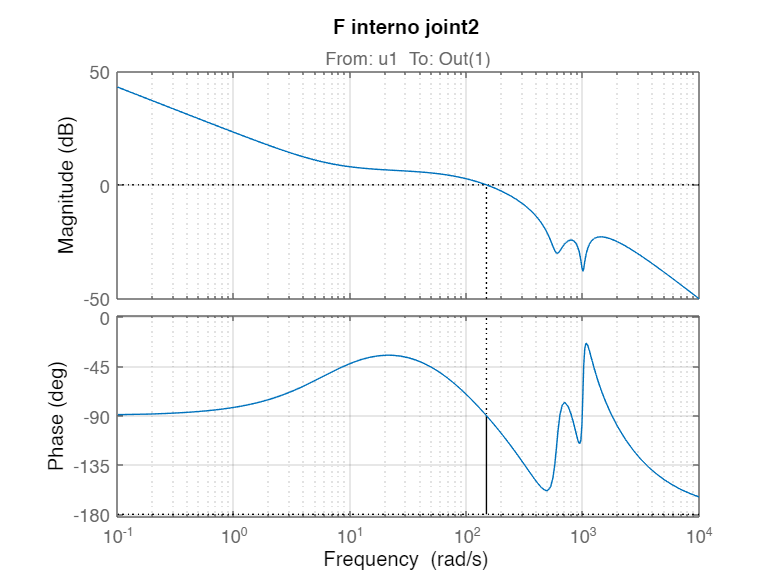

margin(C2_in*modello_continuo_tf_j2)
grid on
title("F interno joint2")

[Y1,T1]=step(F1_in);
t1_1=T1(min(find(Y1>=Y1(end)*0.0952)));
t1_2=T1(min(find(Y1>=Y1(end)*0.6321)));
syms t tau;
eqn1 = t1_1 == t+0.1*tau;
eqn2 = t1_2 == t + tau;
sol=solve([eqn1;eqn2]);
delay1_in=double(sol.t)

delay1_in = 3.5093e-04

if delay1_in < 0
    delay1_in = 0;
end
tau1_in=double(sol.tau)

tau1_in = 0.0104

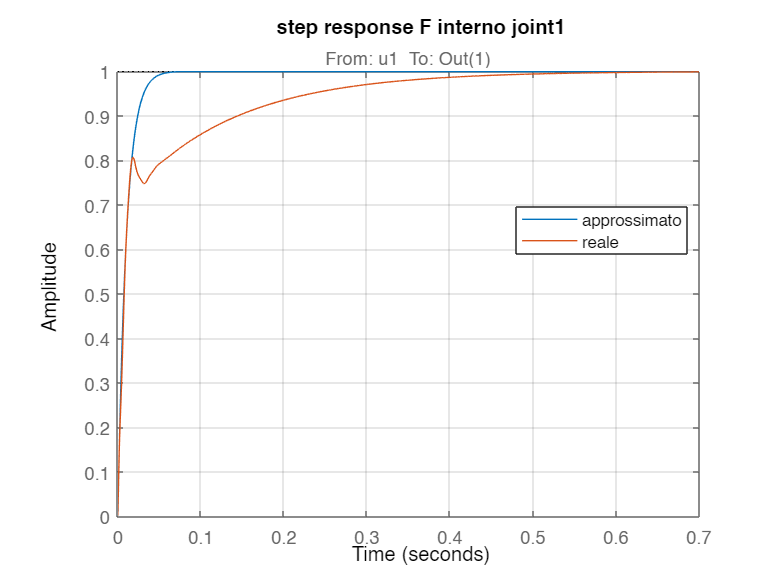

F1_in_approx = tf(1, [tau1_in 1]);
F1_in_approx.OutputDelay=delay1_in;
step(F1_in_approx,F1_in)
title("step response F interno joint1")
legend("approssimato","reale",Location="best")
grid on
% Salvataggio della figura
set(gcf,'renderer','painters')
exportgraphics(gcf,'D:\Github\scara-robot\img\Fint_j1.emf')



[Y2, T2]=step(F2_in);
t2_1=T2(min(find(Y2>=Y2(end)*0.0952)))

t2_1 = 0.0016

t2_2=T2(min(find(Y2>=Y2(end)*0.6321)))

t2_2 = 0.0094

syms t tau
eqn1 = t2_1 == t+0.1*tau;
eqn2 = t2_2 == t + tau;
sol=solve([eqn1;eqn2])

sol = struct with fields:
      t: 14720973900081979/20752587082923245568
    tau: 179710590468533225/20752587082923245568


delay2_in=double(sol.t)

delay2_in = 7.0936e-04

if delay2_in < 0
    delay2_in = 0;
end
tau2_in=double(sol.tau)

tau2_in = 0.0087

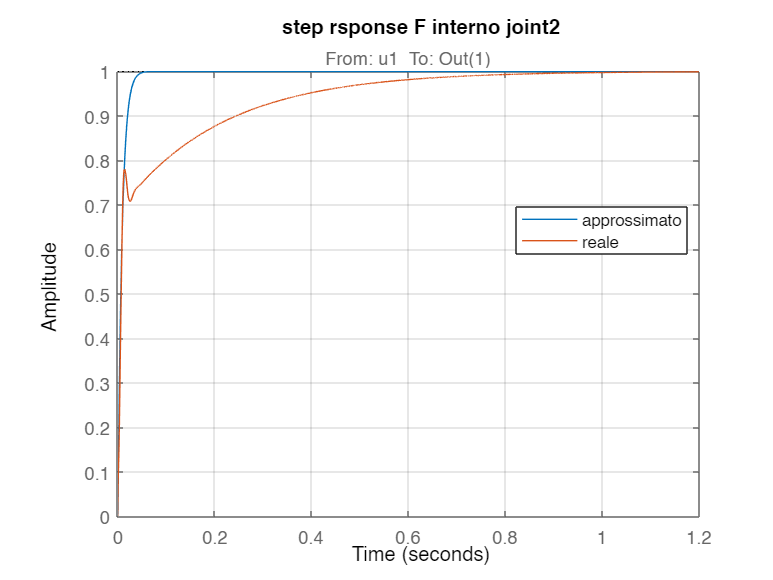

F2_in_approx = tf(1, [tau2_in 1]);
F2_in_approx.OutputDelay=delay2_in;
step(F2_in_approx,F2_in)
title("step rsponse F interno joint2")
legend("approssimato","reale",Location="best")
grid on
% Salvataggio della figura
set(gcf,'renderer','painters')
exportgraphics(gcf,'D:\Github\scara-robot\img\Fint_j2.emf')

M1=tf(1,[tau1_in 1]);
M1.OutputDelay=delay1_in;

M2=tf(1,[tau2_in 1]);
M2.OutputDelay=delay2_in;


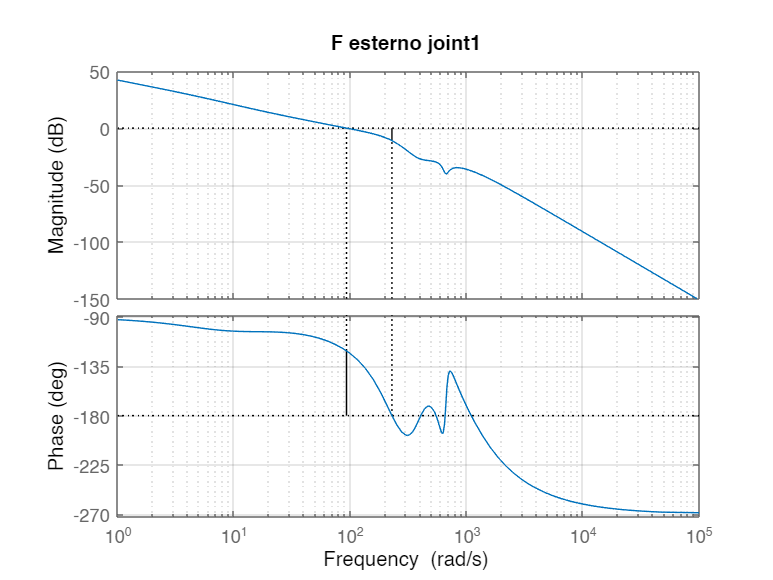


L1_out = C1_out*F1_in/s;
F1_out = feedback(L1_out,1);
margin(L1_out)
grid on
title("F esterno joint1")

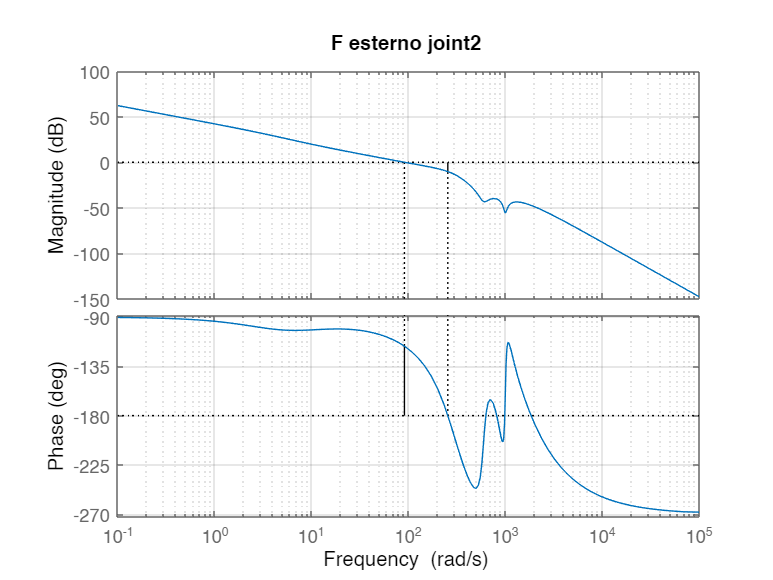


L2_out = minreal(C2_out*F2_in/s);
F2_out = feedback(L2_out,1);
margin(L2_out)
grid on
title("F esterno joint2")

[Y1,T1]=step(F1_out);
t1_1=T1(min(find(Y1>=Y1(end)*0.0952)));
t1_2=T1(min(find(Y1>=Y1(end)*0.6321)));
syms t tau;
eqn1 = t1_1 == t+0.1*tau;
eqn2 = t1_2 == t + tau;
sol=solve([eqn1;eqn2]);
delay1_out=double(sol.t)

delay1_out = 0.0039

if delay1_out < 0
    delay1_out = 0;
end
tau1_out=double(sol.tau)

tau1_out = 0.0102

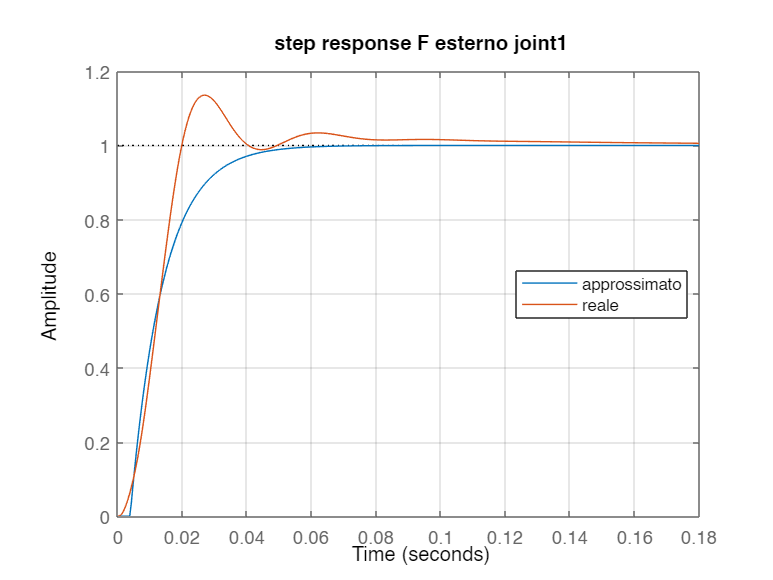

F1_in_approx = tf(1, [tau1_out 1]);
F1_in_approx.OutputDelay=delay1_out;
step(F1_in_approx,F1_out)
title("step response F esterno joint1")
legend("approssimato","reale",Location="best")
grid on
% Salvataggio della figura
set(gcf,'renderer','painters')
exportgraphics(gcf,'D:\Github\scara-robot\img\Fext_j1.emf')




[Y2, T2]=step(F2_out);
t2_1=T2(min(find(Y2>=Y2(end)*0.0952)))

t2_1 = 0.0052

t2_2=T2(min(find(Y2>=Y2(end)*0.6321)))

t2_2 = 0.0132

syms t tau
eqn1 = t2_1 == t+0.1*tau;
eqn2 = t2_2 == t + tau;
sol=solve([eqn1;eqn2])

sol = struct with fields:
      t: 22355210906163893/5188146770730811392
    tau: 46346168951803195/5188146770730811392


delay2_out=double(sol.t)

delay2_out = 0.0043

if delay2_out < 0
    delay2_out = 0;
end
tau2_out=double(sol.tau)

tau2_out = 0.0089

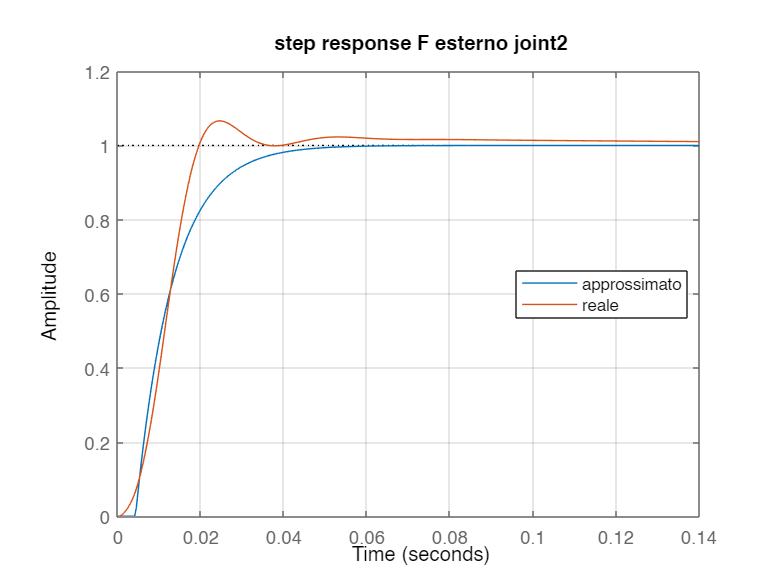

F2_in_approx = tf(1, [tau2_out 1]);
F2_in_approx.OutputDelay=delay2_out;
step(F2_in_approx,F2_out)
title("step response F esterno joint2")
legend("approssimato","reale",Location="best")
grid on
% Salvataggio della figura
set(gcf,'renderer','painters')
exportgraphics(gcf,'D:\Github\scara-robot\img\Fext_j2.emf')

save("./controllers/"+file_controllers+"_ff.mat","C1_out","C1_in","tau1_in", "tau1_out", "M1","C2_out","C2_in","tau2_in", "tau2_out", "M2");